First, let a 3x3 grid that encompass the enitire angx/angy plane. Enter the angles into the original ang2xy and see the results in the image plane.

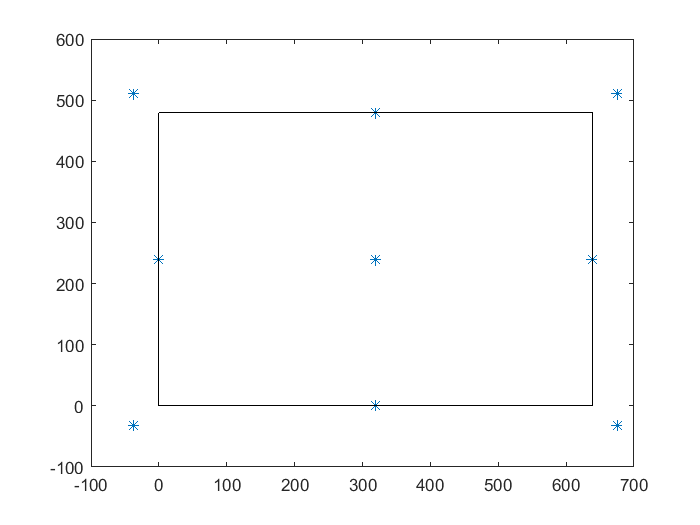

clear, close all
% Load some fw
fw = Pipe.loadFirmware('\\tmund-MOBL1\C$\source\algo_ivcam2\scripts\calibScripts\DODCalib\DODCalibDataset\initScript');
regs2.FRMW.gaurdBandV = single(0);
fw.setRegs(regs2,'');
[regs,luts] = fw.get();
% Create a grid of angles:
[angx,angy] = meshgrid([-2047,0,2047],[-2047,0,2047]);

% Show them on the xy image plane
[xf,yf,~] = myang2xy(angx,angy,regs,0);
plot(xf(:),yf(:),'*');
rectangle('position',[0 0 double(regs.GNRL.imgHsize-1) double(regs.GNRL.imgVsize-1)])

As you can see, the points with angx equal to zero make a vertical line. It makes sense as the return angle of the laser beam doesn't change in x when y varies.

Now we shall see the effect of the zenith. The zenith is the direction of the laser in the coordinates system of the mirror when at rest. The normal of the mirror at rest is [0,0,1].

In theory, when the 'theta_x' angle of the zenith equals to the xfov/4 (the largest opening angle of the mirror), the range of the output angles is [-3*theta_x,theta_x]. 

Let us look at the mapping in this case:

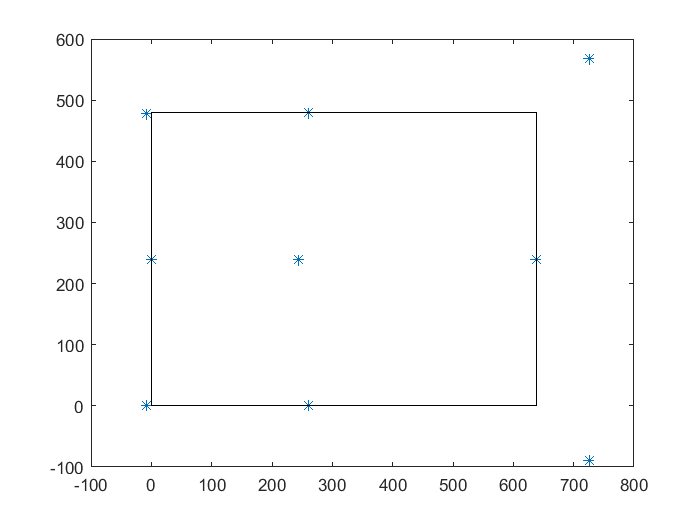

% Assuming 2047 represents the fov/4, I shall add to the x angle an offset of fov/8.
maxAng = 2047;
% [angx,angy] = meshgrid([-maxAng/2,0,maxAng/2],[-maxAng/2,0,maxAng/2]);
[angx,angy] = meshgrid([-maxAng,0,maxAng],[-maxAng,0,maxAng]);
% angx = [-maxAng,-maxAng,-maxAng];
% angy = [maxAng,0,-maxAng];
offSetAngle = (regs.FRMW.xfov/4);
% Get the x,y coordinates with zenith of the same angle
regsZ = regs;
regsZ.FRMW.laserangleH = single(offSetAngle);
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regsZ,0);
plot(xfZ(:),yfZ(:),'*');
rectangle('position',[0 0 double(regs.GNRL.imgHsize-1) double(regs.GNRL.imgVsize-1)])

At first glance, the overall shape is as expected. Except...

It is mirrored! The points that share angx value of fovx/4 (on the right) should be those that look more as a straight line! 

In addition, If we look at the xy coordinates of the points that share angx value of fovx/4 we can see that they do not form a straight line in the image space (while they should).

When I delved into ang2xy function (I analyzed the commented straight forward section after making sure it output the same results as the true function), I noticed that the output direction of the laser after hitting the mirror is calculated using the function:

angles2xyz_orig = @(angx,angy) [ sind(angx) cosd(angx).*sind(angy) cosd(angx).*cosd(angy)]';

This function is known from physics calss and transforms an elevation angle and xy rotation angle into a vector. 

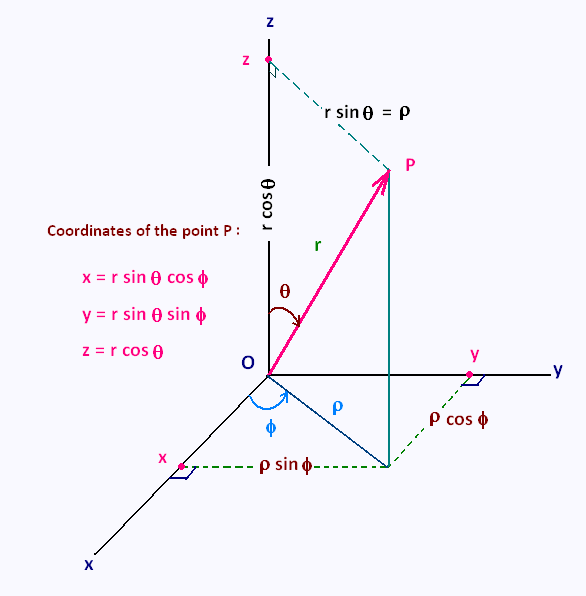

In the image above, theta is  the elevation angle between the z axis and the xy plane, and phi is the rotation angle along the z-axis.

In out case, angx is the rotation angle along the y-axis, and angy is the elevation between the y-axis and the xz plane. From this observation, I conclude that the function should look like:

angles2xyz_fixed = @(angx,angy) [ cosd(angy).*sind(angx) sind(angy) cosd(angy).*cosd(angx)]';

Let us see the difference for a few examples:

angs = [0,0; 0,90; 90,0; 90,90;45,45];
angles2xyz_orig(angs(:,1),angs(:,2))'

ans =          0         0    1.0000
         0    1.0000         0
    1.0000         0         0
    1.0000         0         0
    0.7071    0.5000    0.5000


angles2xyz_fixed(angs(:,1),angs(:,2))'

ans =          0         0    1.0000
         0    1.0000         0
    1.0000         0         0
         0    1.0000         0
    0.5000    0.7071    0.5000


In the 4th and 5th example - the difference is clear.

Let us test the new function and see the points when using it for ang2xy:

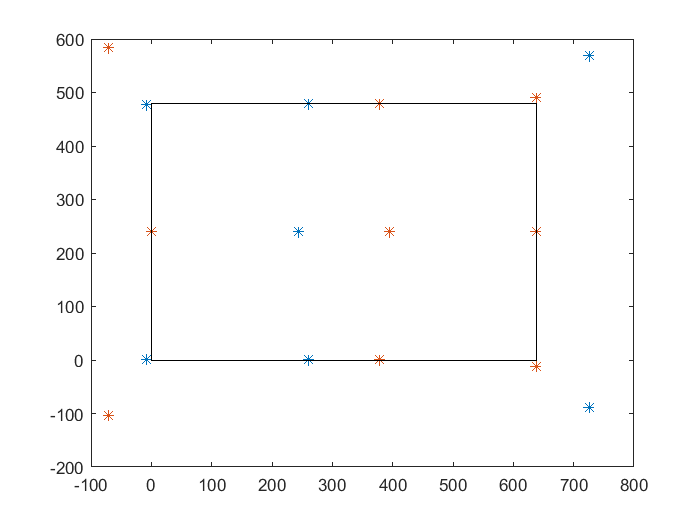

[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regsZ,0);
plot(xfZ(:),yfZ(:),'*');
hold on
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regsZ,1);
plot(xfZ(:),yfZ(:),'*');
rectangle('position',[0 0 double(regs.GNRL.imgHsize-1) double(regs.GNRL.imgVsize-1)])

In red we can see fixed coordiantes. They look extcly as expected. 

Just to make sure, I shall take a column of points that have an angx of fovx/8, and take a zenith of fovx/8 and see the the result is a straight line:

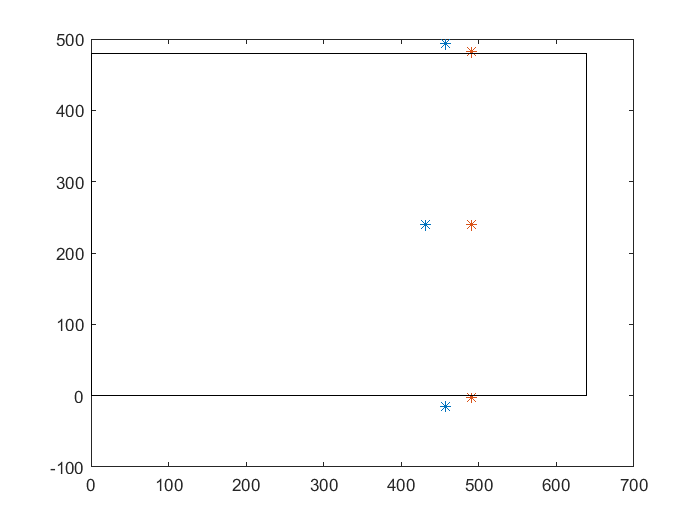

% Assuming 2047 represents the fov/4, I shall add to the x angle an offset of fov/8.
maxAng = 2047;
angx = [maxAng/2,maxAng/2,maxAng/2];
angy = [maxAng,0,-maxAng];
offSetAngle = (regs.FRMW.xfov/8);
% Get the x,y coordinates with zenith of the same angle
regsZ = regs;
regsZ.FRMW.laserangleH = single(offSetAngle);
figure
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regsZ,0);
figure
plot(xfZ(:),yfZ(:),'*');
hold on
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regsZ,1);
plot(xfZ(:),yfZ(:),'*');
rectangle('position',[0 0 double(regs.GNRL.imgHsize-1) do

    
uble(regs.GNRL.imgVsize-1)])




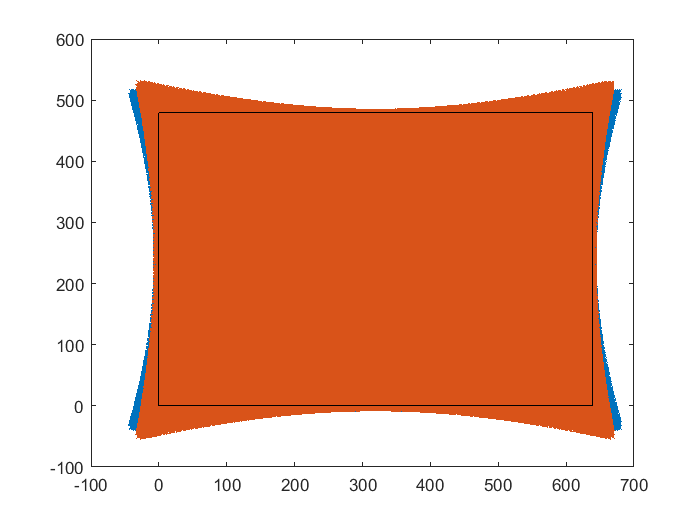

maxAng = 2047;

[angx,angy] = meshgrid([-maxAng:10:maxAng],[-maxAng:10:maxAng]);


offSetAngle = 0;%(regs.FRMW.xfov/8);
% Get the x,y coordinates with zenith of the same angle
figure
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regs,0);
figure
plot(xfZ(:),yfZ(:),'*');
hold on
[xfZ,yfZ,xynrmZ] = myang2xy(angx,angy,regs,1);
plot(xfZ(:),yfZ(:),'*');
rectangle('position',[0 0 double(regs.GNRL.imgHsize-1) double(regs.GNRL.imgVsize-1)])